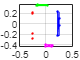

clear;clc;
load("PointFangXingShiCe.mat");

face1_transformed = [face1_transformed(2,:);face1_transformed(3,:);face1_transformed(1,:)];
face2_transformed = [face2_transformed(2,:);face2_transformed(3,:);face2_transformed(1,:)];
face3_transformed = [face3_transformed(2,:);face3_transformed(3,:);face3_transformed(1,:)];
face4_transformed = [face4_transformed(2,:);face4_transformed(3,:);face4_transformed(1,:)];
BoundPoint1 = [BoundPoint1(2);BoundPoint1(3);BoundPoint1(1)];
BoundPoint2 = [BoundPoint2(2);BoundPoint2(3);BoundPoint2(1)];

figure;
hold on
scatter3(face1_transformed(1, :), face1_transformed(2, :), face1_transformed(3, :), 'r.');
scatter3(face2_transformed(1, :), face2_transformed(2, :), face2_transformed(3, :), 'g.');
scatter3(face3_transformed(1, :), face3_transformed(2, :), face3_transformed(3, :), 'b.');
scatter3(face4_transformed(1, :), face4_transformed(2, :), face4_transformed(3, :), 'm.');

% 平面 1
PlaneParaIn = [];
[PlaneParaOut,TrianglePoints] = planefit(face1_transformed, ...
    PlaneParaIn,BoundPoint1,BoundPoint2);

plot3(TrianglePoints(1,[1:3,1]),TrianglePoints(2,[1:3,1]),TrianglePoints(3,[1:3,1]),'r')
plot3(TrianglePoints(1,[4:6,4]),TrianglePoints(2,[4:6,4]),TrianglePoints(3,[4:6,4]),'r')


% 平面 2
PlaneParaIn = [];
[PlaneParaOut,TrianglePoints] = planefit(face2_transformed, ...
    PlaneParaIn,BoundPoint1,BoundPoint2);

plot3(TrianglePoints(1,[1:3,1]),TrianglePoints(2,[1:3,1]),TrianglePoints(3,[1:3,1]),'g')
plot3(TrianglePoints(1,[4:6,4]),TrianglePoints(2,[4:6,4]),TrianglePoints(3,[4:6,4]),'g')


% 平面 3
PlaneParaIn = [];
[PlaneParaOut,TrianglePoints] = planefit(face3_transformed, ...
    PlaneParaIn,BoundPoint1,BoundPoint2);

plot3(TrianglePoints(1,[1:3,1]),TrianglePoints(2,[1:3,1]),TrianglePoints(3,[1:3,1]),'b')
plot3(TrianglePoints(1,[4:6,4]),TrianglePoints(2,[4:6,4]),TrianglePoints(3,[4:6,4]),'b')


% 平面 4
PlaneParaIn = [];
[PlaneParaOut,TrianglePoints] = planefit(face4_transformed, ...
    PlaneParaIn,BoundPoint1,BoundPoint2);

plot3(TrianglePoints(1,[1:3,1]),TrianglePoints(2,[1:3,1]),TrianglePoints(3,[1:3,1]),'m')
plot3(TrianglePoints(1,[4:6,4]),TrianglePoints(2,[4:6,4]),TrianglePoints(3,[4:6,4]),'m')




box on
grid on
axis equal